# tutorial March19 Exercise 2

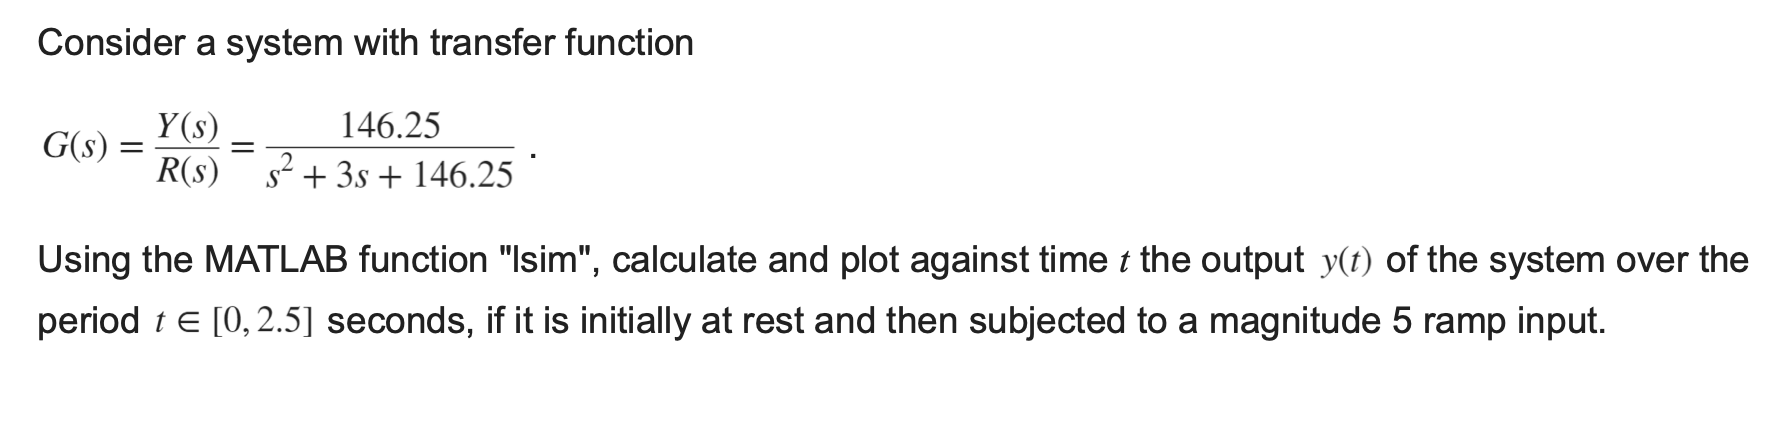

clearvars, close all, clc
G = tf(146.25, [1, 3, 146.25])


G =
 
        146.2
  -----------------
  s^2 + 3 s + 146.2
 
Continuous-time transfer function.


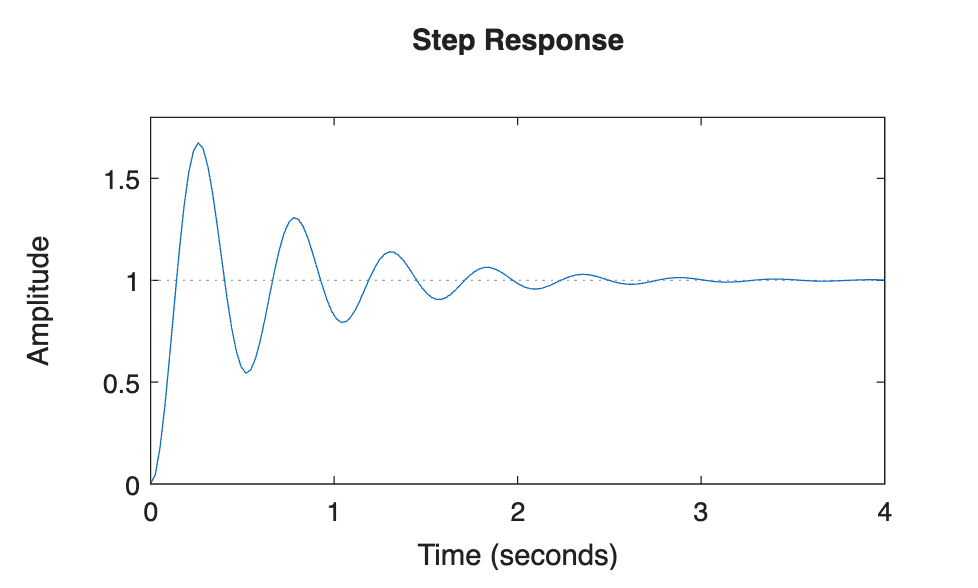


figure(1)
step(G)


delt = 0.08

delt = 0.0800

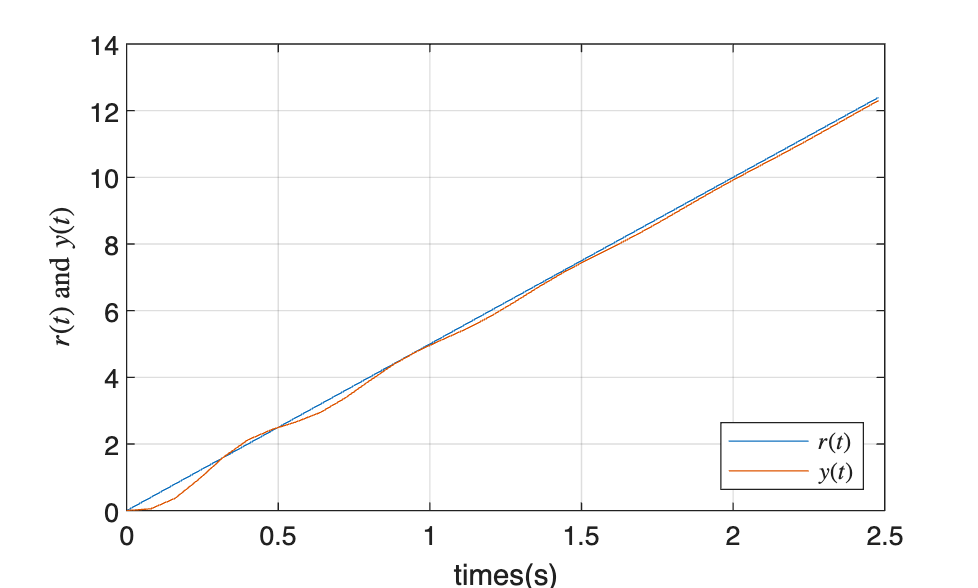

t1 = [0:delt:2.5]';
r1 = 5.0*t1; % generate ramp input

y1 = lsim(G,r1,t1);
figure(2)
plot(t1,r1,'DisplayName','$r(t)$')
hold on
plot(t1,y1,'DisplayName','$y(t)$')
hold on
xlabel('times(s)')
ylabel('$r(t)$ and $y(t)$','Interpreter','latex')
grid on
legend('Location','southeast','Interpreter','latex')